# Step by step introduction to building and using active inference models

## Supplementary Code for Active Inference Modelling Tutorial

Authors: Ryan Smith, Karl J. Friston, Christopher J. Whyte

Initial Setup:

1. Add SPM12, its DEM toolbox, and the example scripts folder to your MATLAB path.

% Cleanup Actions:
clear all       % Clear all variables from the workspace.
close all       % Close all open figure windows.

% Random Number Setup:
rng('shuffle')  % Ensure varied random sequences in simulations.


**Simulation Options (set these after building the model):**

-     - Sim = 1: Simulates a single trial, aiming to reproduce Fig. 8. 

-                Note: Results may vary due to random sampling.

-     - Sim = 2: Simulates multiple trials with the left context active, aiming to reproduce Fig. 10. 

-     - Sim = 3: Simulates reversal learning. The left context is active initially and reverses later, aiming to reproduce Fig. 11. 

-     - Sim = 4: Performs parameter estimation on simulated data with reversal learning, aiming to reproduce the top panel of Fig. 17.

-     - Sim = 5: Executes parameter estimation on simulated data from multiple participants and conducts model comparison, aiming to reproduce the bottom panel of Fig. 17. Results and inputs for group analyses are saved.

% Risk-seeking Parameter (rs1) Usage:
rs1 = 4;        % Use 4 or 8 to reproduce Fig. 8 (Sim = 1), 3 or 4 for Figs. 10 and 11 (Sim = 2 or 3).
                % rs1 has no impact for Sim = 4 or Sim = 5.

% Example Simulation:
Sim = 1;

% When Sim = 5: 
% - Set PEB = 1 to run group-level analyses.
PEB = 0;        % Note: After running Sim = 5 once, you can load GCM_2 and GCM_3 and run the PEB section separately, saving time in subsequent runs.

% Running Sections Separately:
% - After model building, you can run individual sections by selecting them and clicking 'Run Section'.

## 1. Set up model structure

### Specification of Time Points: T

The model involves a sequence of decisions or epochs within a trial, denoted by T.

The agent navigates through the following stages within a trial:

- - Starts in an initial 'Start' state.

- - Decides to either seek a 'Hint' or directly choose a slot machine ('Choose Left' or 'Choose Right').

- - Based on the previous decision, either leverages the 'Hint' to make a slot machine choice or returns to the 'Start' state after choosing a slot machine.

T = 3;

### Defining Priors for Initial States: D and d

Priors (D) represent initial beliefs about the states in the generative process.

**Context Prior (D{1}): **We establish a belief that the 'left better' context (where the left slot machine is favored) is the true context.

D{1} = [1 0]';  % Options: {'left better','right better'}

**Behavior Prior (D{2}): **The agent is presumed to begin every trial in the 'start' state, prior to making a choice or seeking a hint.

D{2} = [1 0 0 0]'; % States: {'start','hint','choose-left','choose-right'}

### Defining Prior Beliefs About Initial States in the Generative Model: d

Prior beliefs (d) are optional and enable the simulation of learning about initial states. These are termed 'Dirichlet concentration parameters' and are not confined to a [0, 1] range.

These parameters are incrementally updated after each trial, reflecting the agent's changing beliefs about initial states. For example, believing in the 'left better' context in trial 1 modifies d{1} in trial 2 to d{1} = [1.5 0.5]', adjusting with a certain learning rate.

Higher values indicate stronger confidence in beliefs about initial states, hence influencing the beliefs' rate of change after new observations. 

**Context Beliefs (d{1}): **The agent initially believes that both contexts ('left better' and 'right better') are equally probable, but has low confidence in these beliefs.

d{1} = [.25 .25]';  % Options: {'left better','right better'}

**Behavior Beliefs (d{2}): **The agent is fully confident that it will initiate a trial in the 'start' state.

d{2} = [1 0 0 0]'; % States: {'start','hint','choose-left','choose-right'}

### Defining State-Outcome Mappings and Beliefs: A and a

The probabilities of outcomes given each state in the generative process are defined in A. A contains one matrix per outcome modality and is also, by default, the beliefs in the generative model.

Mapping from states to observed hints (outcome modality 1) is initially defined. Here, rows relate to observations, columns to the first state factor (context), and the third dimension to behavior. Every column must sum to 1 as it is a probability distribution.

Both contexts generate 'No Hint' observation across all behavior states by default.

Ns = [length(D{1}) length(D{2})]; % Number of states in each state factor (2 and 4)
for i = 1:Ns(2) 
    A{1}(:,:,i) = [1 1; % No Hint
                   0 0; % Machine-Left Hint
                   0 0];% Machine-Right Hint
end

'Get Hint' behavior state generates a hint about the better slot machine, based on context state.

pHA = 1; % Hint accuracy probability, set to 1 by default. 
A{1}(:,:,2) = [0     0;      % No Hint
               pHA 1-pHA;    % Machine-Left Hint
               1-pHA pHA];   % Machine-Right Hint

Mapping between states and wins/losses is defined next. 'Start' and 'Get Hint' behavior states do not generate win/loss observations.

for i = 1:2
    A{2}(:,:,i) = [1 1;  % Null
                   0 0;  % Loss
                   0 0]; % Win
end

Choosing the left machine (behavior state 3) generates wins with varying probability (pWin) based on context state.

pWin = .8; % Win probability, set to .8 by default.
A{2}(:,:,3) = [0      0;     % Null        
               1-pWin pWin;  % Loss
               pWin 1-pWin]; % Win

Choosing the right machine (behavior state 4) has win probabilities inverse to choosing the left machine.

A{2}(:,:,4) = [0      0;     % Null
               pWin 1-pWin;  % Loss
               1-pWin pWin]; % Win 

An identity mapping between behavior states and observed behaviors ensures the agent acknowledges behaviors are executed as intended. Each row corresponds to each behavior state.

for i = 1:Ns(2) 
    A{3}(i,:,i) = [1 1];
end

### Specifying Prior Beliefs About State-Outcome Mappings: a

Prior beliefs about state-outcome mappings (a) in the generative model can be specified, though this is optional and would simulate learning state-outcome mappings if provided.

Learning involves modifying the values of matrix entries based on observed outcomes when the agent believed it was in a certain state.

For instance, if a win was observed while the agent believed it was in the 'left better' context and 'choose left machine' behavior state, the probability value corresponding to that location in the state outcome-mapping might change (e.g., a{2}(3,1,3) might change from .8 to 1.8).

Setting up matrix (a) might involve: 

- Initially identifying it with the generative process (A),

- Multiplying the values by a large number to prevent learning all aspects of the matrix (allowing the distribution shape to change very slowly),

- Adjusting elements to differ from the generative process as desired.

Example of simulating **learning the reward probabilities:**

    % a{1} = A{1}*200;
    % a{2} = A{2}*200;
    % a{3} = A{3}*200;
    % a{2}(:,:,3) =  [0  0;  % Null        
    %                .5 .5;  % Loss
    %                .5 .5]; % Win
    % a{2}(:,:,4) =  [0  0;  % Null        
    %                .5 .5;  % Loss
    %                .5 .5]; % Win

Example of simulating **learning the hint accuracy:**

    % a{1} = A{1}*200;
    % a{2} = A{2}*200;
    % a{3} = A{3}*200;
    % a{1}(:,:,2) =  [0     0;     % No Hint
    %                .25   .25;    % Machine-Left Hint
    %                .25   .25];   % Machine-Right Hint

### Controlled Transitions and Transition Beliefs: B{:,:,u} and b(:,:,u)

The transition matrices **B** specify the probabilistic transitions between hidden states under each action or control state. Columns of B represent states at time t, and rows represent states at time t+1.

**Context State Transitions:** B{1}(:,:,1) describes transitions for the "context" state factor. Since the agent cannot control the context state and the context remains stable within a trial, there's only 1 action, and the matrix is an identity matrix indicating that each state persists:

    B{1}(:,:,1) = [1 0;  % 'Left Better' Context
                   0 1]; % 'Right Better' Context

**Behavior State Transitions: **B{2}(:,:,u) describes transitions for the "behavior" state factor. The agent can control the behavior state, and there are 4 possible actions to be specified:

    Action 1: Move to the Start state from any other state

    B{2}(:,:,1) = [1 1 1 1;  % Start State
                   0 0 0 0;  % Hint
                   0 0 0 0;  % Choose Left Machine
                   0 0 0 0]; % Choose Right Machine

    Action 2: Move to the Hint state from any other state

    B{2}(:,:,2) = [0 0 0 0;  % Start State
                   1 1 1 1;  % Hint
                   0 0 0 0;  % Choose Left Machine
                   0 0 0 0]; % Choose Right Machine

    Action 3: Move to the Choose Left state from any other state

    B{2}(:,:,3) = [0 0 0 0;  % Start State
                   0 0 0 0;  % Hint
                   1 1 1 1;  % Choose Left Machine
                   0 0 0 0]; % Choose Right Machine

    Action 4: Move to the Choose Right state from any other state

    B{2}(:,:,4) = [0 0 0 0;  % Start State
                   0 0 0 0;  % Hint
                   0 0 0 0;  % Choose Left Machine
                   1 1 1 1]; % Choose Right Machine  

### Prior Beliefs About State Transitions in the Generative Model (b)

In this example, learning of transition beliefs (b) will not be simulated. However, when it is desired to simulate such learning, the idea is to accumulate **Dirichlet concentration parameters**, which are updated after each trial based on the agent's belief about being in a particular state at time t and transitioning to another state at t+1. Just like with a, b is a set of matrices with the same structure as B.

### Preferred Outcomes: C and c

Here, prior preferences are specified, encoded as log probabilities. These prior preferences influence the agent's behavior by making certain outcomes more or less desirable.

We define a matrix per outcome modality with each row corresponding to an observation and each column representing a time point. Negative values indicate lower preference, and positive values indicate a high preference. Stronger preferences promote riskier choices and reduced information-seeking.

Determine the number of outcomes in each outcome modality:

No = [size(A{1},1) size(A{2},1) size(A{3},1)];

Initialize C matrices with **zero preference for all outcomes**:

C{1} = zeros(No(1),T); % Hints
C{2} = zeros(No(2),T); % Wins/Losses
C{3} = zeros(No(3),T); % Observed Behaviors

Define the '**loss aversion**' magnitude (**la**) and '**reward seeking**' magnitude (**rs**). The rs is divided by 2 at the third time point to encode a smaller win if taking the hint before choosing a slot machine.

la = 1; 
rs = rs1; 

Specify preferences in C{2} for wins/losses:

C{2}(:,:) = [0  0   0   ;  % Null
             0 -la -la  ;  % Loss
             0  rs  rs/2]; % Win: The rs is divided by 2 at the third time point to encode a smaller win if taking the hint before choosing a slot machine.

### Optional: Learning Preferences with c

Optionally, one can simulate preference learning by specifying a **Dirichlet distribution over preferences** (**c**). This is not demonstrated in the provided code. However, the general idea is that the preference magnitude for an outcome would increase each time that outcome is observed, based on the assumption that preferences naturally increase for more familiar situations.

### Allowable policies: U or V

Each policy is a sequence of actions over time that the agent can consider. Policies can be specified as 'shallow' (looking only one step ahead), as specified by **U**. Or policies can be specified as 'deep' (planning actions all the way to the end of the trial), as specified by **V**. Both U and V must be specified for each state factor as the third matrix dimension. This will simply be all 1s if that state is not controllable.

Example of specifying U:

% Np = 4; % Number of policies
% Nf = 2; % Number of state factors
% 
% U         = ones(1,Np,Nf);
% 
% U(:,:,1) = [1 1 1 1]; % Context state is not controllable
% U(:,:,2) = [1 2 3 4]; % All four actions in B{2} are allowed


For our simulations, we will specify V, where rows correspond to time points and should be length T-1 (here, 2 transitions, from time point 1 to time point 2, and time point 2 to time point 3):

Np = 5; % Number of policies
Nf = 2; % Number of state factors

V         = ones(T-1,Np,Nf);

V(:,:,1) = [1 1 1 1 1;
            1 1 1 1 1]; % Context state is not controllable

V(:,:,2) = [1 2 2 3 4;
            1 3 4 1 1];

For V(:,:,2), columns left to right indicate policies allowing: 

- staying in the start state 

- taking the hint then choosing the left machine

- taking the hint then choosing the right machine

- choosing the left machine right away (then returning to start state)

- choosing the right machine right away (then returning to start state)

### Habits: E and e

Optional: a columns vector with one entry per policy, indicating the prior probability of choosing that policy (i.e., independent of other beliefs). 

We will not equip our agent with habits in our example simulations, but this could be specified as a follows if one wanted to include a strong habit to choose the 4th policy:

% E = [.1 .1 .1 .6 .1]';

To incorporate habit learning, where policies become more likely after each time they are chosen, one can also specify concentration parameters by specifying e. For example:

% e = [1 1 1 1 1]';

### Additional optional parameters

**Eta**: Learning rate (0-1) controlling the update magnitude of concentration parameters after each trial (if learning is enabled).

**Omega**: Forgetting rate (0-1) controlling the reduction in concentration parameter magnitudes after each trial (if learning is enabled). Useful in environments where true parameters can change over time.

**Beta:** Expected precision of expected free energy (G) over policies. Lower values increase the influence of habits (E) and otherwise make policy selection less deterministic.

**Alpha:** Inverse temperature or action precision parameter controlling randomness in action selection. Higher values indicate less randomness.

**ERP:** Controls the degree of belief resetting at each time point in a trial when simulating neural responses. 1 indicates no resetting, and priors smoothly carry over. Higher values indicate more resetting.

**Tau:** Time constant for evidence accumulation. Controls the magnitude of updates at each iteration of gradient descent. Larger values lead to smaller updates and slower convergence time, but promote greater stability in posterior beliefs.

eta = 0.5;  % Default: 0.5. Modify to observe effects on model behavior.
omega = 1;  % Default: 1 (no forgetting). Values < 1 indicate higher forgetting rates.
beta = 1;   % Default: 1. Modify to observe effects on policy selection.
alpha = 32; % Any positive number. 32 is fairly high; an extremely high value (e.g., 512) can be used for deterministic action.
erp = 1;    % Default: 1. Modify to observe effects on simulated neural and behavioral responses.
tau = 12;   % Adjust to observe effects on simulated neural and behavioral responses.
     

**Note:** If these values are left unspecified, they are assigned default values when running simulations. These default values can be found within the spm_MDP_VB_X script (and in the spm_MDP_VB_X_tutorial script we provide in this tutorial).

### Other optional constants.

**Chi: **Occam's window parameter for update threshold in deep temporal models. This parameter controls how quickly convergence is 'cut off' during lower-level evidence accumulation by setting an uncertainty threshold below which no additional trial epochs are simulated.

**Zeta:** Occam's window for policies. This parameter sets the threshold at which a policy ceases to be considered if its free energy becomes too high. Higher values indicate a higher threshold.

chi = 1/64;  % Default: 1/64. Smaller numbers (e.g., 1/128) indicate a higher confidence threshold.

zeta = 3;  % Default: 3. A higher value (e.g., 6) means a policy needs to be significantly worse 
           % than the best policy to be 'pruned'.
         

**Note: **The spm_MDP_VB_X function is also equipped with broader functionality allowing incorporation of mixed (discrete and continuous) models, plotting, simulating Bayesian model reduction during simulated rest/sleep, among others. We do not describe these in detail here, but are described in the documentation at the top of the function.

### True states and outcomes: s and o.

Optionally, one may specify true states and outcomes for some or all time points using s and o. If these are not specified, they will be generated by the generative process.

**Example: **Specifying true states at time point 1 as left context and start state:

s = [1;  % Context: 'left better'
     1]; % Behavior: 'start'
     % Additional time points (rows for each state factor) are not 
     % specified (implicit 0s).

**Example:** Specifying observations at time point 1 as No Hint, Null, and Start behavior observations.

o = [1;  % Hint: 'No Hint'
     1;  % Outcome: 'Null'
     1]; % Behavior: 'start'
     % Additional time points (rows for each outcome modality) are 
     % not specified (implicit 0s).

## 2. Define Markov Decision Process (MDP) Structure

Basic Setup

--------------------------------------------------------------------------

mdp.T = T;          % Number of time steps
mdp.V = V;          % Allowable (deep) policies
% mdp.U = U;        % Alternatively, we could use shallow policies (specifying U instead of V).

Probabilistic Mappings and Preferences

--------------------------------------------------------------------------

mdp.A = A;          % State-outcome mapping
mdp.B = B;          % Transition probabilities between states
mdp.C = C;          % Preferred states or outcomes
mdp.D = D;          % Priors over initial states

Learning and Adjustment Parameters

--------------------------------------------------------------------------

mdp.d = d;          % Enable learning priors over initial states
mdp.eta = eta;      % Learning rate
mdp.omega = omega;  % Forgetting rate
mdp.alpha = alpha;  % Action precision
mdp.beta = beta;    % Expected precision of expected free energy over policies
mdp.erp = erp;      % Degree of belief resetting at each time step
mdp.tau = tau;      % Time constant for evidence accumulation

Optionally Including Other Parameters

--------------------------------------------------------------------------

% Note: The following parameters are optional and are commented out in this example.
% mdp.E = E;        % Habits
% mdp.a = a;        % Learning state-outcome mappings
% mdp.b = b;        % Learning transition probabilities
% mdp.c = c;        % Learning preferences
% mdp.e = e;        % Learning habits
% mdp.s = s;        % True states
% mdp.o = o;        % True outcomes
% mdp.chi = chi;    % Confidence threshold for evidence accumulation
% mdp.zeta = zeta;  % Occam's window for policy pruning

Labeling for Plotting and Analysis

--------------------------------------------------------------------------

label.factor{1}   = 'contexts';       label.name{1}    = {'left-better','right-better'};
label.factor{2}   = 'choice states';  label.name{2}    = {'start','hint','choose left','choose right'};
label.modality{1} = 'hint';           label.outcome{1} = {'null','left hint','right hint'};
label.modality{2} = 'win/lose';       label.outcome{2} = {'null','lose','win'};
label.modality{3} = 'observed action';label.outcome{3} = {'start','hint','choose left','choose right'};
label.action{2}   = {'start','hint','left','right'};
mdp.label = label;

Clear Temporary Variables

--------------------------------------------------------------------------

clear beta alpha eta omega la rs % Clearing variables to avoid conflicts in later simulations

### Matrix Dimension Check

% Use a script to check if all matrix-dimensions are correct:
mdp = spm_MDP_check(mdp)

mdp = struct with fields:
        T: 3
        V: [2×5×2 double]
        A: {[3×2×4 double]  [3×2×4 double]  [4×2×4 double]}
        B: {[2×2 double]  [4×4×4 double]}
        C: {[3×3 double]  [3×3 double]  [4×3 double]}
        D: {[2×1 double]  [4×1 double]}
        d: {[2×1 double]  [4×1 double]}
      eta: 0.5
    omega: 1
    alpha: 32
     beta: 1
      erp: 1
      tau: 12
    label: [1×1 struct]
    Aname: {'hint'  'win/lose'  'observed action'}
    Bname: {'contexts'  'choice states'}

### Simulation Condition 1

**Single Trial Simulations: **Utilizing the defined generative process and model, a single trial is simulated using the 'spm_MDP_VB_X_tutorial' script. This script is specific to this tutorial and integrates a learning rate (eta) for initial state priors (d) and a forgetting rate (omega), which are not present in the SPM version as of 05/08/21.

- **Visualization of Simulated Neural Responses: **Use the standard plotting routines to visualize the simulated neural responses and the agent's behavior and beliefs over the trial.

- **Plot of Simulated Neural Responses: **Plot Local Field Potentials (LFPs)

- **Plot of Posterior Beliefs and Behavior: **Plot trial specifics - posterior beliefs and behavior

For interpretations of the resulting figures, please refer to the main text.

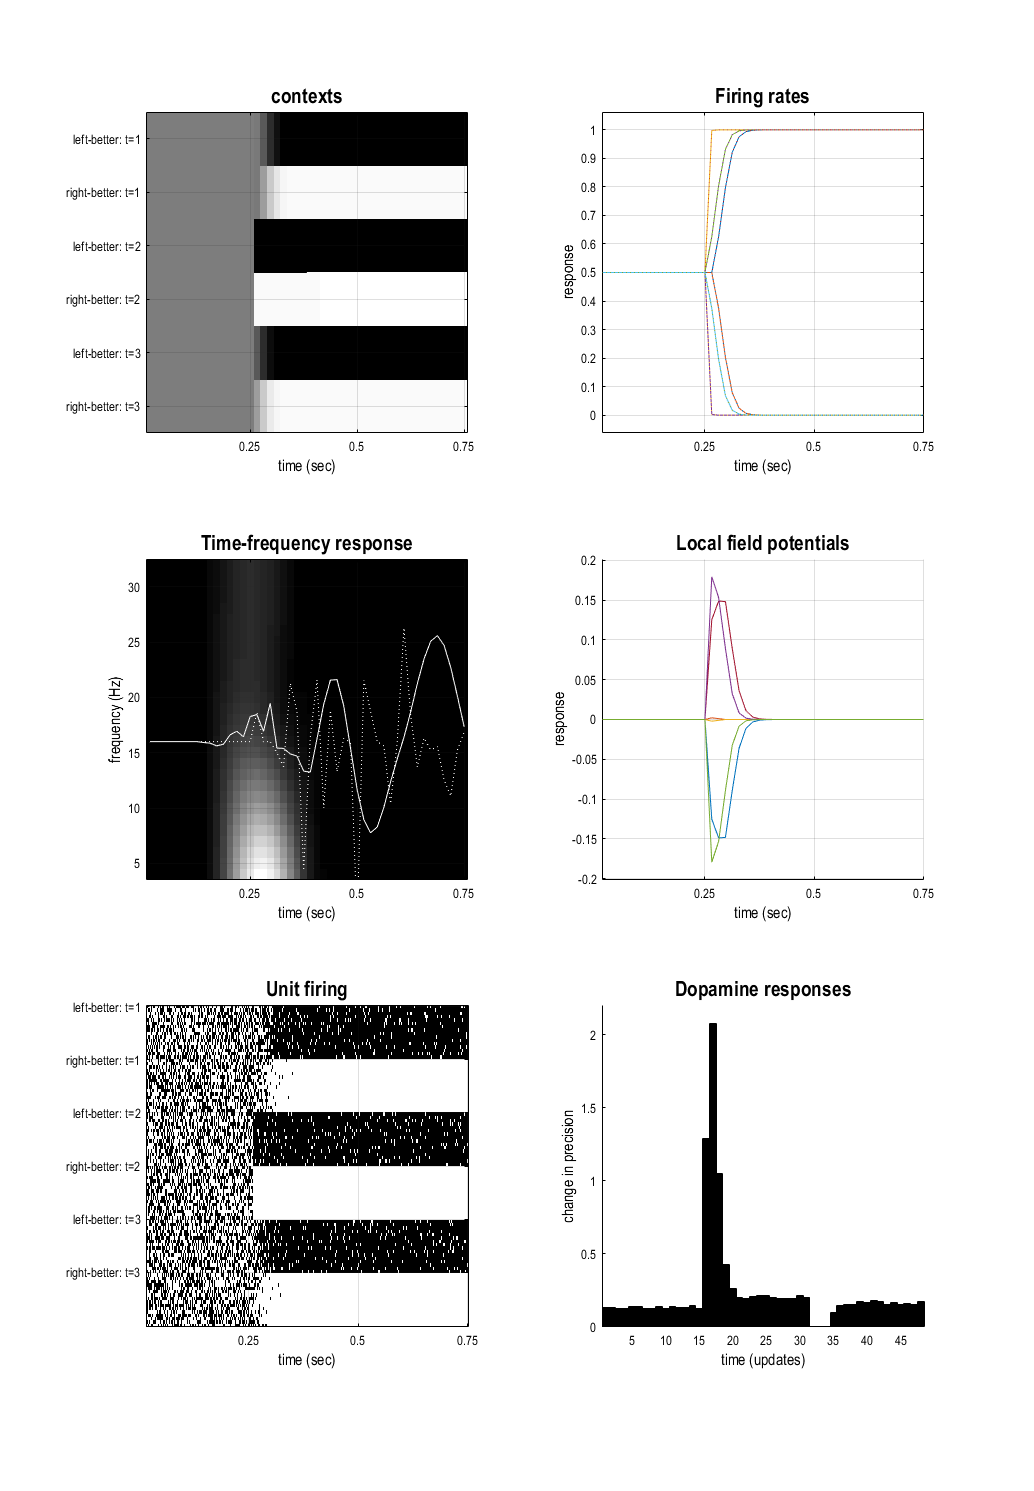

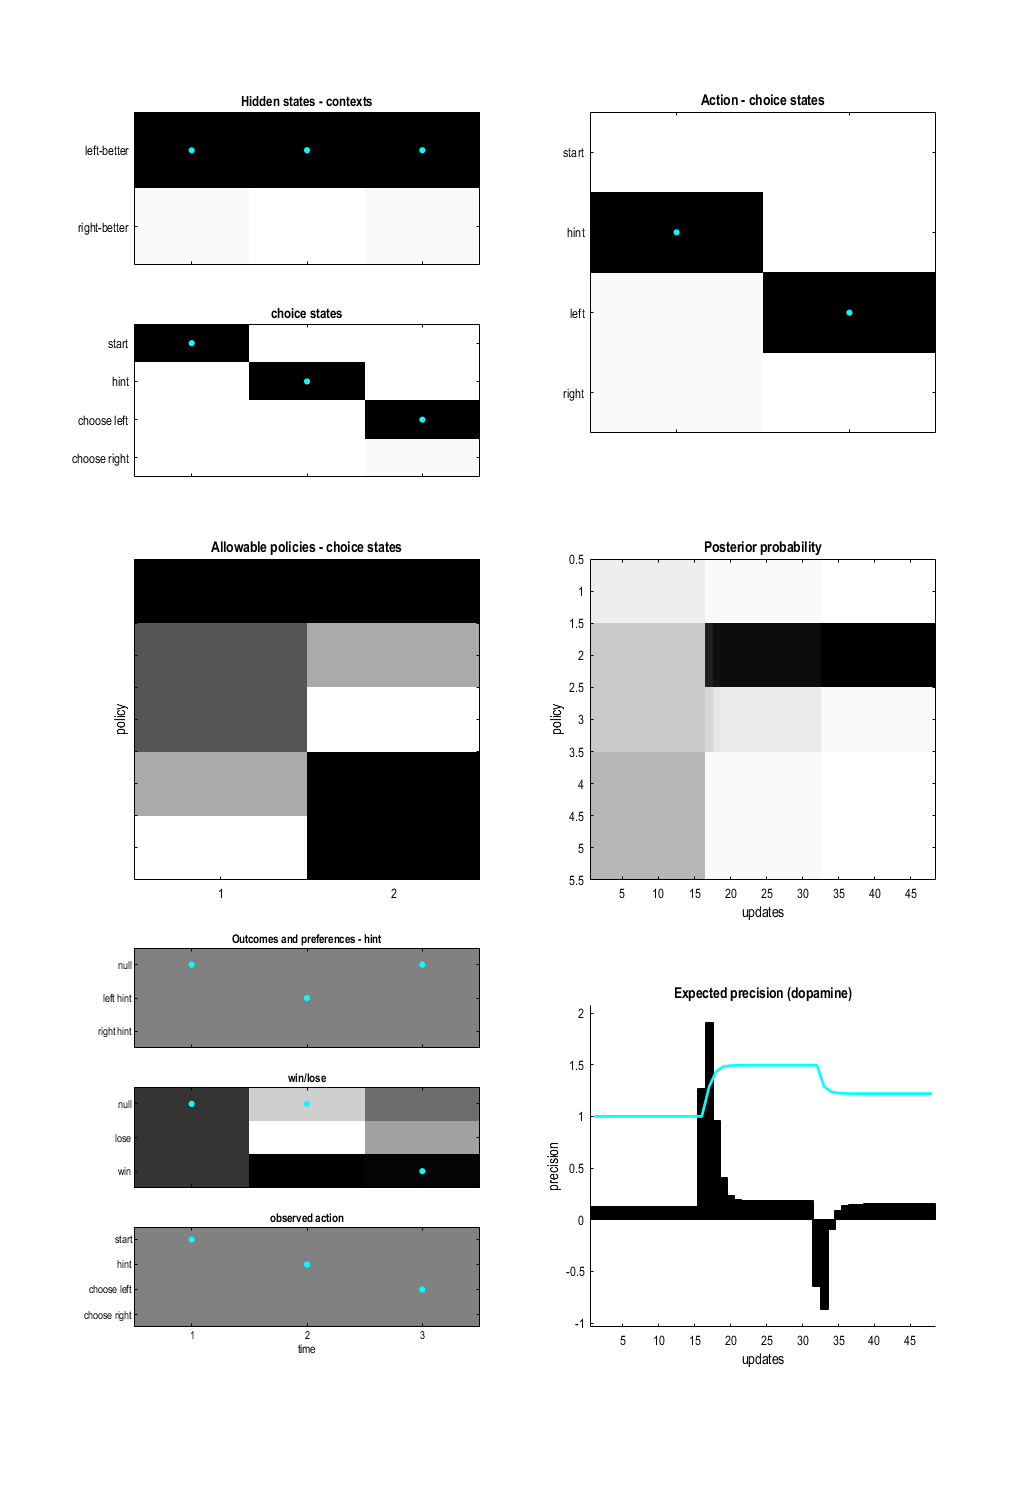

simulate(mdp, 1)

## Simulate Condition 2

**Multi-Trial Simulations:** Expanding the MDP structure to conduct and analyze multiple trials.

- **Define the Number of Trials:** 30;

- **Visualization of Simulated Neural Responses Across All Trials:** Use the standard plotting routines to visualize the agent's behavior across all simulated trials.

- **Plot of Behavior Across All Trials:** Plot the behavior across all trials

For interpretations of the resulting figures, please refer to the main text.

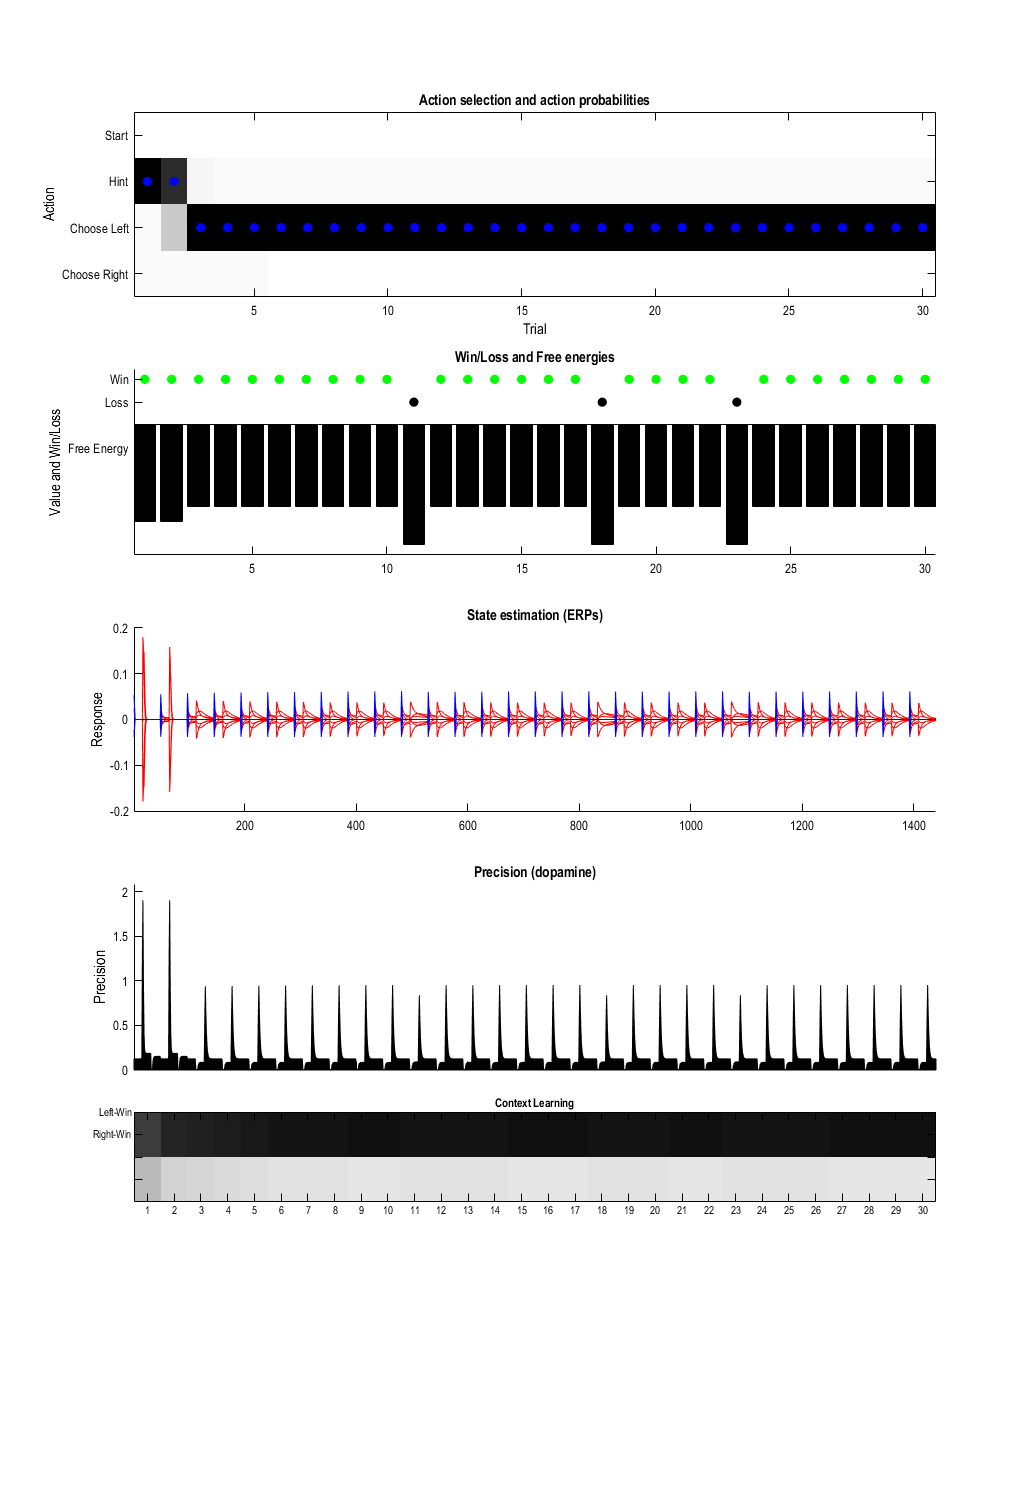

simulate(mdp, 2)

## Simulate Condition 3

**Simulating Reversal Learning:** Conducting simulations to assess the agent's behavior and learning during reversal learning conditions, wherein the environment's context switches partway through the simulation.

- **Define the Number of Trials: **32;  

- **Visualization of Simulated Neural Responses Across All Trials: **Using standard plotting routines to visualize the agent's behavior across all simulated trials.

- **Plot of Behavior Across All Trials: **Plotting the behavior across all trials

For interpretations of the resulting figures, please refer to the main text.

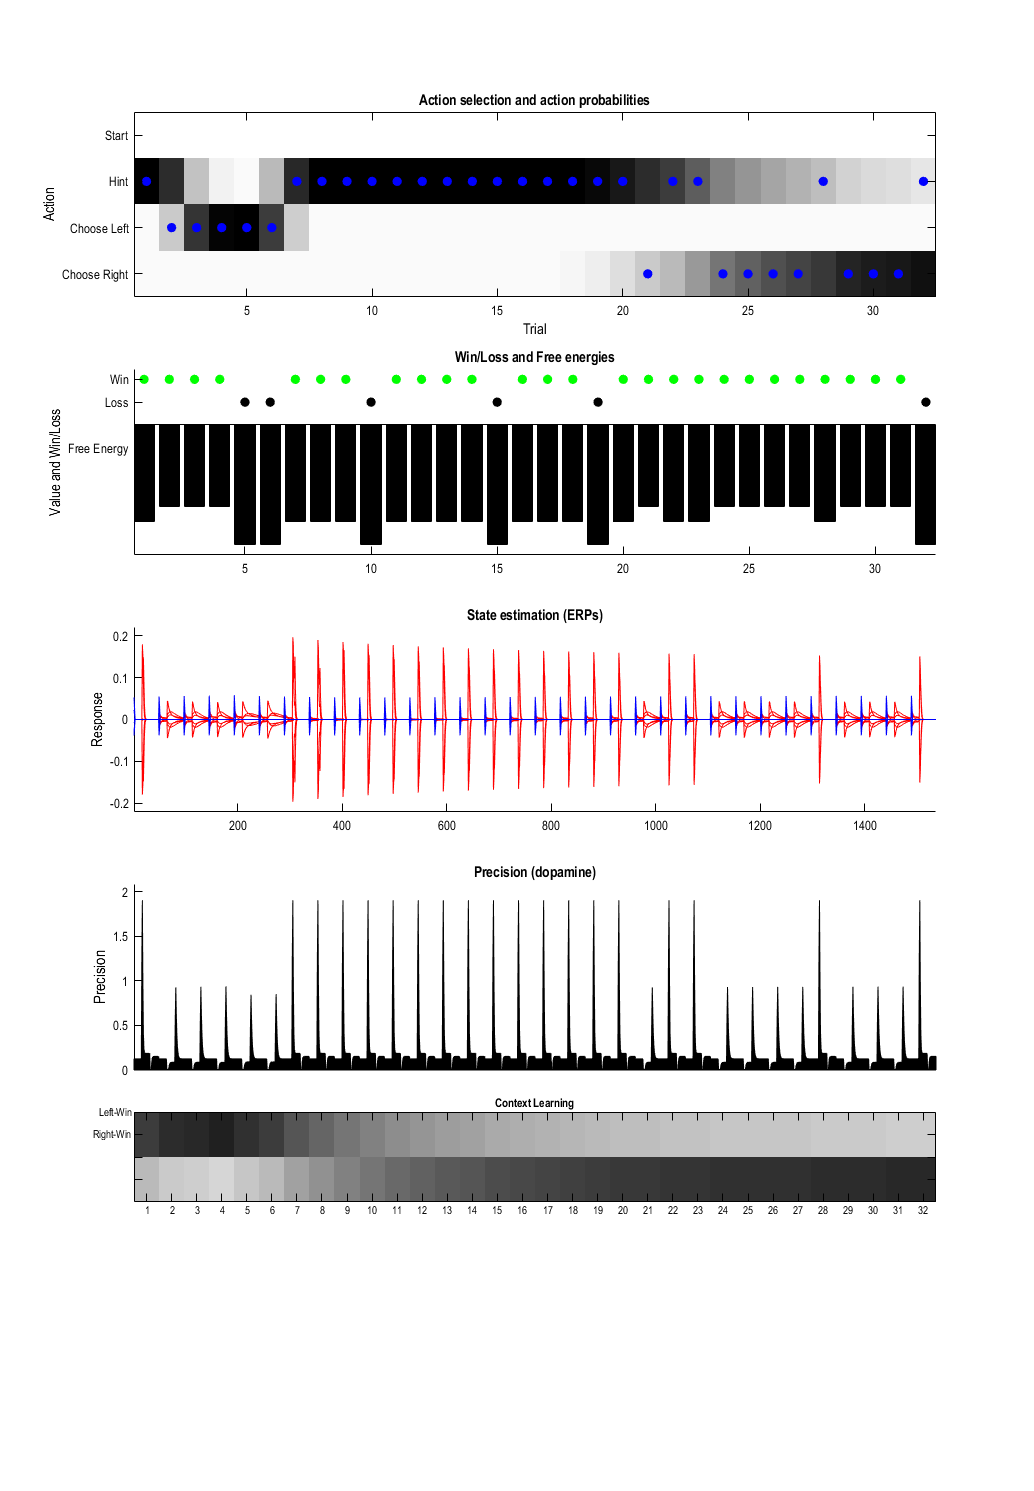

simulate(mdp, 3)

## Simulate Condition 4

**Model Inversion to Recover Parameters (Action Precision and Risk-Seeking)**

- **Visualization of prior and posterior means & posterior covariance**

- **Compare prior with posterior estimates**

LL: -44.368203 
LL: -44.378204 
LL: -44.313456 
LL: -44.378204 
LL: -44.388210 
LL: -44.323430 
LL: -44.313456 
LL: -44.323430 
LL: -44.258896 
EM:(+): 1     F: 0.000e+00 dF predicted: 4.527e+00 LL: -40.500896 
LL: -40.509012 
LL: -40.462940 
LL: -40.509012 
LL: -40.517132 
LL: -40.471037 
LL: -40.462940 
LL: -40.471037 
LL: -40.425206 
 actual: 3.527e+00 (21.61 sec)
EM:(+): 2     F: 3.527e+00 dF predicted: 2.446e+00 LL: -38.490616 
LL: -38.497754 
LL: -38.467070 
LL: -38.497754 
LL: -38.504895 
LL: -38.474197 
LL: -38.467070 
LL: -38.474197 
LL: -38.443762 
 actual: 1.888e+00 (20.27 sec)
EM:(+): 3     F: 5.414e+00 dF predicted: 1.303e+00 LL: -37.479838 
LL: -37.486538 
LL: -37.468278 
LL: -37.486538 
LL: -37.493240 
LL: -37.474974 
LL: -37.468278 
LL: -37.474974 
LL: -37.456957 
 actual: 9.800e-01 (24.12 sec)
EM:(+): 4     F: 6.394e+00 dF predicted: 5.775e-01 LL: -37.022252 
LL: -37.028803 
LL: -37.018328 
LL: -37.028803 
LL: -37.035356 
LL: -37.024879 
LL: -37.018328 
LL: -37.024879 

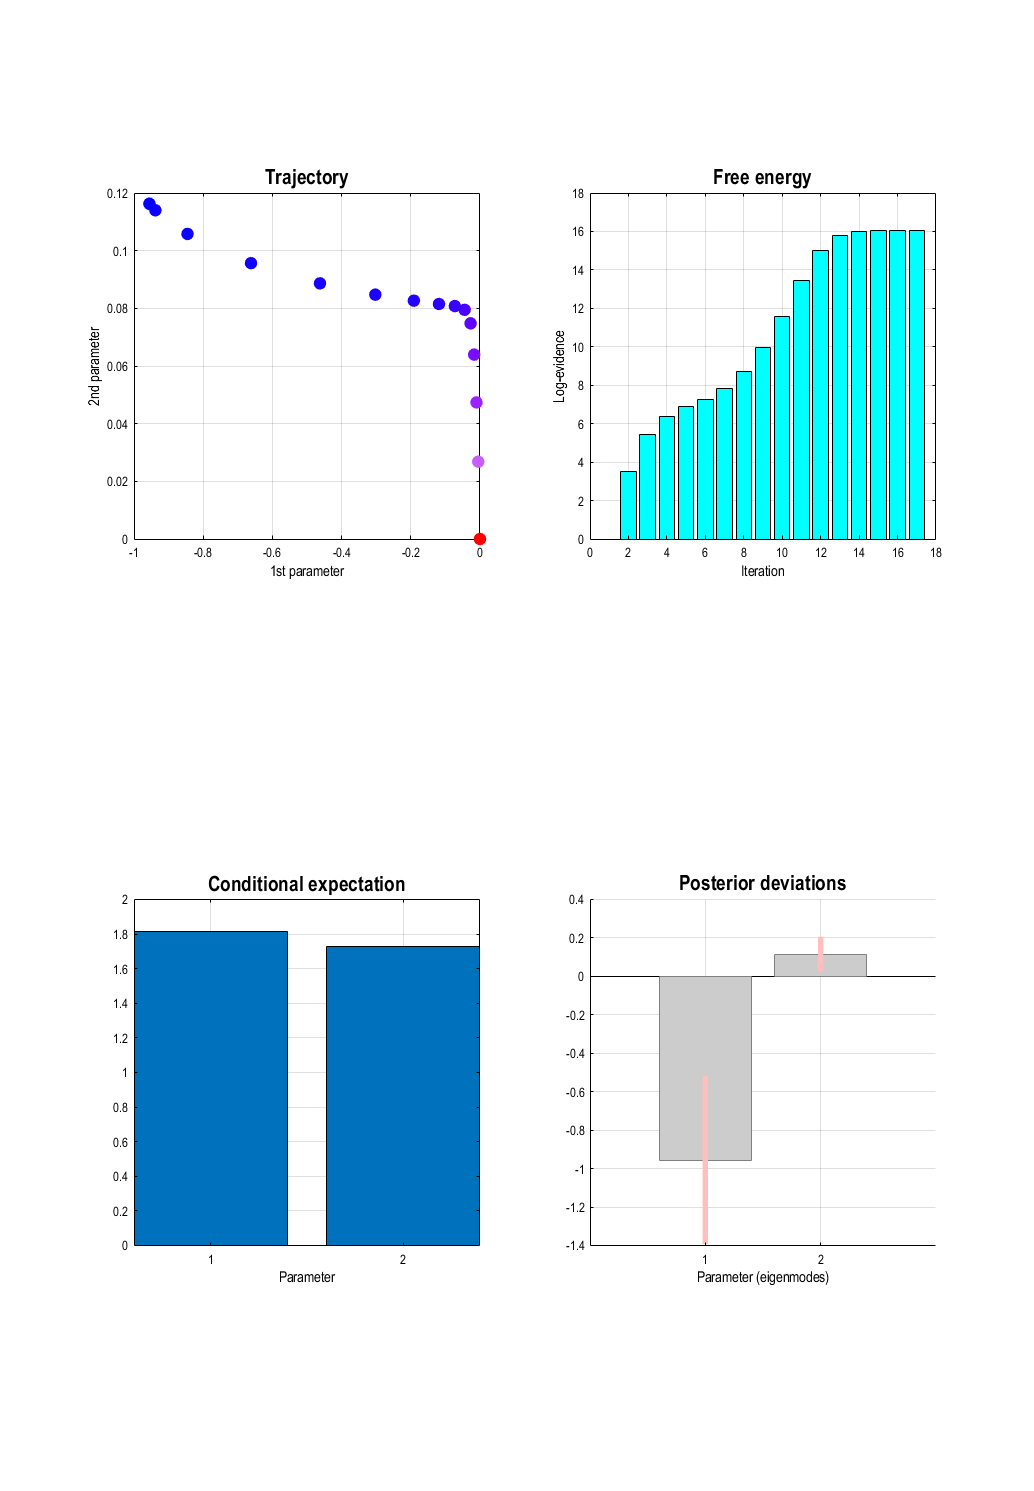

EM:(+): 17     F: 1.604e+01 dF predicted: 6.578e-18  convergence


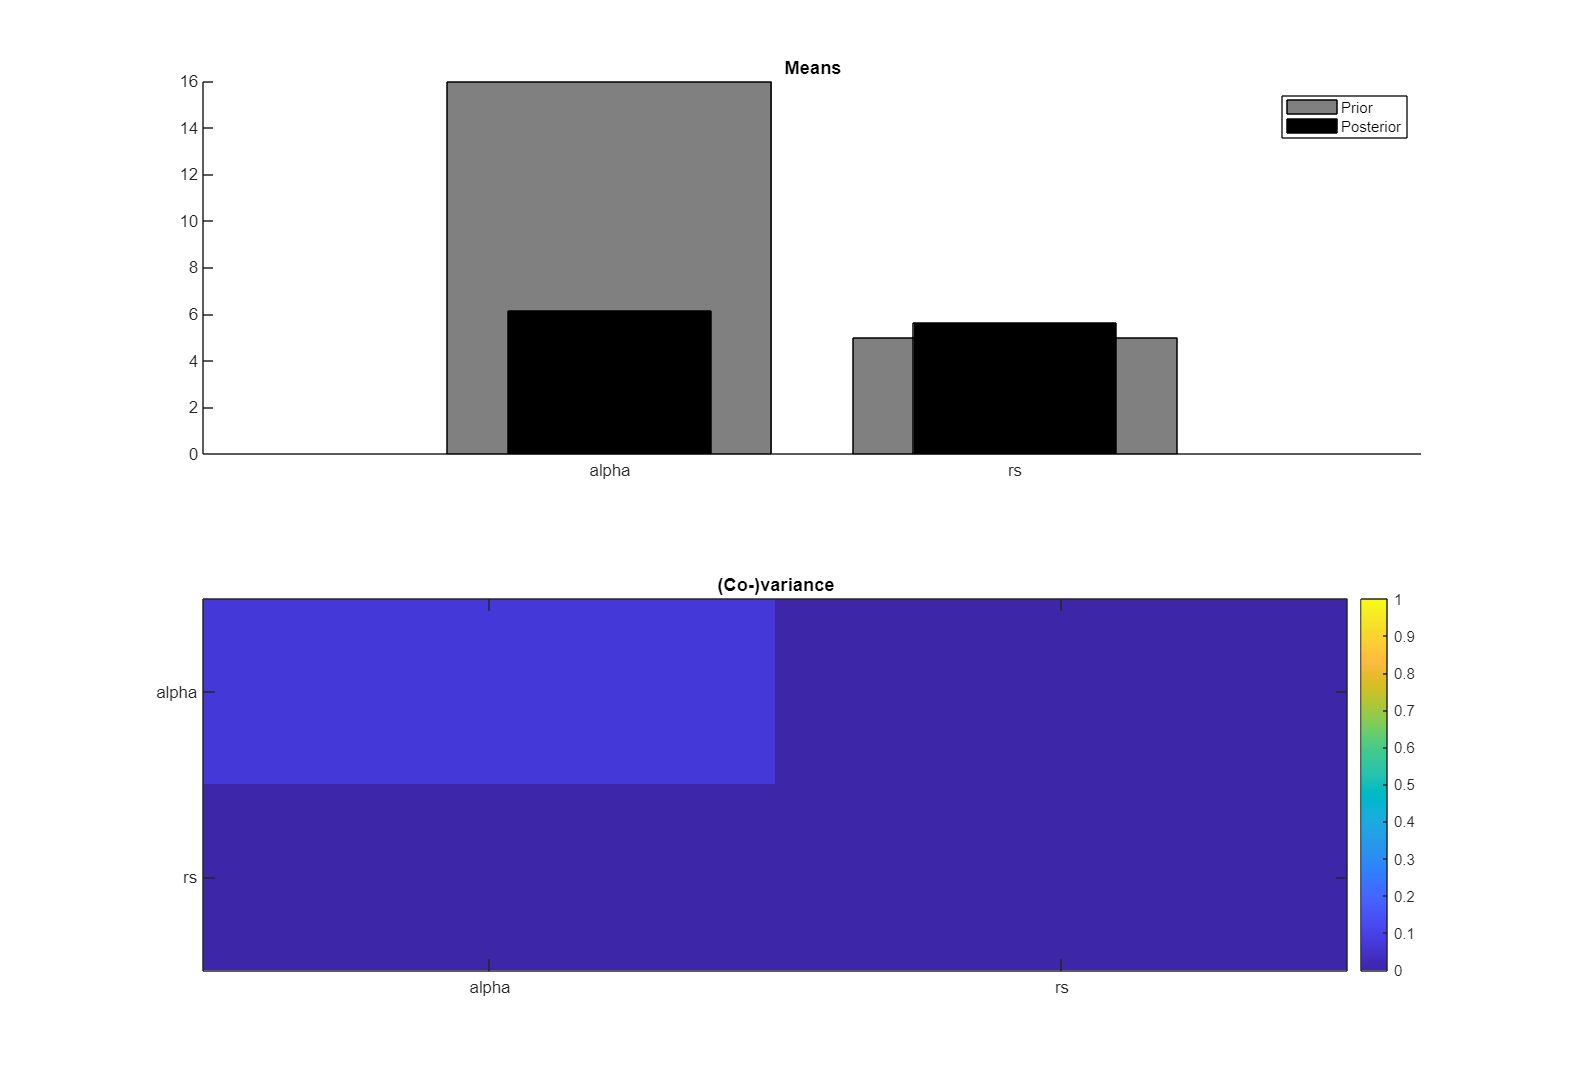

simulate(mdp, 4)

## Simulate Condition 5 (Takes a bit of time)

**Reversal Learning Trial Setup:** Setting up a sequence of trials for a reversal learning task. The task starts with a 'left-better' context and switches to a 'right-better' context halfway through.

**Generate Free Energies for Model Fits (2-Parameter Model without Eta): **In this 2-parameter model case, the correlations appear quite high for rs, and moderate for alpha

- This extended section continues the generation of free energies for model fits using a 2-parameter model (without eta). It involves simulating participant behavior, estimating model parameters, and then evaluating and storing various performance metrics.

**Generate Free Energies for 3 Parameter Model (with eta): **In this 3-parameter model case, the correlations appear high for rs and alpha, and moderate for learning rate. Note, however, that a wider range of values should be simulated to confirm recoverability in actual studies (and with a larger number of subjects).

**Compute Log-likelihood and Action Probabilities for Best-Fit Model**

**Aggregate Log-Likelihood and Total Probability**

**Compute average log-likelihood and action probability**

**Store Parameters for Recoverability Assessment**

**Random Effects Bayesian Model Comparison (of Free Energies of best-fit models per participant)**

**Bayesian Model Comparison**

**Perform Bayesian Model Selection and display the protected exceedance probability**

**Recoverability Assessment: **Here we can also compute the strength of the relationship between true and estimated parameters to check recoverability. 

**Hierarchical Bayes (Optional, conditional on PEB flag):** Using PEB, you can test  the evidence for a 'full' model that assumes a group difference in all parameters and simpler models that assume no differences in one or more parameters. This allows testing evidence for a difference (or for no difference) in estimated parameters. PEB uses a general linear (random effects) model, which also allows testing evidence for individual difference effects (e.g., age, symptom severity). If you select the 'Second-level effect - Group' you can see that rs is significantly different between groups

See relevant literature on these routines, e.g., Friston, Litvak, Oswal, Razi, Stephan, van Wijk, Ziegler, & Zeidman, 2016; Zeidman, P., Jafarian, A., Seghier, M. L., Litvak, V., et al., 2019

--------------------------------------------------------------------------

Please see main text for further information about how to interpet results figures

simulate(mdp, 5)

LL: -52.489333 
LL: -52.503689 
LL: -52.558513 
LL: -52.489637 
LL: -52.503689 
LL: -52.518051 
LL: -52.572895 
LL: -52.503994 
LL: -52.558513 
LL: -52.572895 
LL: -52.627866 
LL: -52.558818 
LL: -52.489637 
LL: -52.503994 
LL: -52.558818 
LL: -52.489941 
EM:(+): 1     F: 0.000e+00 dF predicted: 1.679e+01 LL: -40.802248 
LL: -40.811934 
LL: -40.828113 
LL: -40.802222 
LL: -40.811934 
LL: -40.821625 
LL: -40.837812 
LL: -40.811908 
LL: -40.828113 
LL: -40.837812 
LL: -40.854171 
LL: -40.828089 
LL: -40.802222 
LL: -40.811908 
LL: -40.828089 
LL: -40.802196 
 actual: 1.137e+01 (32.55 sec)
EM:(+): 2     F: 1.137e+01 dF predicted: 3.077e+00 LL: -38.688431 
LL: -38.697063 
LL: -38.695097 
LL: -38.688239 
LL: -38.697063 
LL: -38.705700 
LL: -38.703734 
LL: -38.696872 
LL: -38.695097 
LL: -38.703734 
LL: -38.701957 
LL: -38.694907 
LL: -38.688239 
LL: -38.696872 
LL: -38.694907 
LL: -38.688047 
 actual: 2.024e+00 (32.57 sec)
EM:(+): 3     F: 1.340e+01 dF predicted: 9.540e-01 LL: -37.830739 
L

LL: -88.744295 
LL: -88.771737 
LL: -88.911209 
LL: -88.747774 
LL: -88.771737 
LL: -88.799190 


Unrecognized function or variable 'DCM'.
Error in Simplified_Step_by_Step_AI_Guide>simulate (line 465)
            field = fieldnames(DCM.M.pE);

function simulate(mdp, Sim)

%--------------------------------------------------------------------------
if Sim == 1

    % Single Trial Simulations
    %--------------------------------------------------------------------------
    % Utilizing the defined generative process and model, a single trial is
    % simulated using the 'spm_MDP_VB_X_tutorial' script. This script
    % is specific to this tutorial and integrates a learning rate (eta)
    % for initial state priors (d) and a forgetting rate (omega), which
    % are not present in the SPM version as of 05/08/21.
    %--------------------------------------------------------------------------
    
    % Simulation of the Single Trial
    %----------------------------------------------------------------------
    MDP = spm_MDP_VB_X_tutorial(mdp);
    
    % Visualization of Simulated Neural Responses
    %----------------------------------------------------------------------
    % Use the standard plotting routines to visualize the simulated neural
    % responses and the agent's behavior and beliefs over the trial.

    % Plot of Simulated Neural Responses
    %----------------------------------------------------------------------
    spm_figure('GetWin','Figure 1'); clf  % Prepare the window for behavioral display
    spm_MDP_VB_LFP(MDP);  % Plot Local Field Potentials (LFPs)
    
    % Plot of Posterior Beliefs and Behavior
    %----------------------------------------------------------------------
    spm_figure('GetWin','Figure 2'); clf  % Prepare the window for posterior beliefs display
    spm_MDP_VB_trial(MDP);  % Plot trial specifics - posterior beliefs and behavior
    
    % For interpretations of the resulting figures, please refer to the main text.
    
    % End of the 'if Sim == 1' condition

elseif Sim == 2
    
    % Multi-Trial Simulations
    %--------------------------------------------------------------------------
    % Expanding the MDP structure to conduct and analyze multiple trials.
    %--------------------------------------------------------------------------
    
    % Define the Number of Trials
    %----------------------------------------------------------------------
    N = 30;  % Setting the number of trials to be simulated
    
    % Preparing the MDP Structure for Multiple Trials
    %----------------------------------------------------------------------
    MDP = mdp;  % Assigning the single-trial MDP structure to a new variable
    [MDP(1:N)] = deal(MDP);  % Replicating the MDP structure N times
    
    % Running the Simulations for All Trials
    %----------------------------------------------------------------------
    MDP = spm_MDP_VB_X_tutorial(MDP);  % Simulating all N trials
    
    % Visualization of Simulated Neural Responses Across All Trials
    %----------------------------------------------------------------------
    % Use the standard plotting routines to visualize the agent's behavior
    % across all simulated trials.

    % Plot of Behavior Across All Trials
    %----------------------------------------------------------------------
    spm_figure('GetWin','Figure 3'); clf  % Prepare the window for behavioral display
    spm_MDP_VB_game_tutorial(MDP);  % Plot the behavior across all trials
    
    % For interpretations of the resulting figures, please refer to the main text.
    
    % End of the 'elseif Sim == 2' condition


elseif Sim == 3
    
    % Simulating Reversal Learning
    %--------------------------------------------------------------------------
    % Conducting simulations to assess the agent's behavior and learning 
    % during reversal learning conditions, wherein the environment's context 
    % switches partway through the simulation.
    %--------------------------------------------------------------------------
    
    % Define the Number of Trials
    %----------------------------------------------------------------------
    N = 32;  % Setting the number of trials for the simulation
    
    % Preparing the MDP Structure for Multiple Trials
    %----------------------------------------------------------------------
    MDP = mdp;  % Assigning the single-trial MDP structure to a new variable
    [MDP(1:N)] = deal(MDP);  % Replicating the MDP structure N times
    
    % Setting the Context for Initial and Latter Half of Trials
    %----------------------------------------------------------------------
    for i = 1:N/8
        MDP(i).D{1} = [1 0]';  % Setting 'left-better' context for early trials
    end
    
    for i = (N/8)+1:N
        MDP(i).D{1} = [0 1]';  % Switching to 'right-better' context for the remaining trials
    end
    
    % Running the Simulations for All Trials
    %----------------------------------------------------------------------
    MDP = spm_MDP_VB_X_tutorial(MDP);  % Simulating all N trials
    
    % Visualization of Simulated Neural Responses Across All Trials
    %----------------------------------------------------------------------
    % Using standard plotting routines to visualize the agent's behavior
    % across all simulated trials.

    % Plot of Behavior Across All Trials
    %----------------------------------------------------------------------
    spm_figure('GetWin','Figure 4'); clf  % Preparing the window for behavioral display
    spm_MDP_VB_game_tutorial(MDP);  % Plotting the behavior across all trials
    
    % For interpretations of the resulting figures, please refer to the main text.
    
    % End of the 'elseif Sim == 3' condition


elseif Sim == 4
    
    % Model Inversion to Recover Parameters (Action Precision and Risk-Seeking)
    %==========================================================================
    
    % Close all previous figures
    %----------------------------------------------------------------------
    close all
    
    % Generate Simulated Behavior under Specific Parameter Values
    %==========================================================================
    
    % Define number of trials
    N = 32;  
    
    MDP = mdp;
    [MDP(1:N)] = deal(MDP);
    
    % Set the contexts for trials
    for i = 1:N/8
        MDP(i).D{1} = [1 0]';  % 'left-better' context in early trials
    end
    
    for i = (N/8)+1:N
        MDP(i).D{1} = [0 1]';  % Switch to 'right-better' context for latter trials
    end
    
    % Specify true parameter values to recover during estimation
    alpha = 4;  % Lower action precision
    la = 1;     % Keeping loss aversion at 1
    rs = 6;     % Higher risk-seeking
    
    C_fit = [0  0   0 ;    
             0 -la -la  ;  
             0  rs  rs/2];  
    
    [MDP(1:N).alpha] = deal(alpha); 
    
    for i = 1:N
        MDP(i).C{2} = C_fit; 
    end
    
    % Simulate the trials with defined settings
    MDP = spm_MDP_VB_X_tutorial(MDP);
    
    
    % Model Inversion to Recover Original Parameters
    %==========================================================================
    
    % Carry over true values for use in estimation script
    mdp.la_true = la;   
    mdp.rs_true = rs;   
    
    % Define the MDP model to be estimated and parameters to optimize
    DCM.MDP = mdp;                  
    DCM.field = {'alpha','rs'};      
    
    % Add true observations and actions
    DCM.U = {MDP.o};              
    DCM.Y = {MDP.u};              
    
    % Run parameter estimation
    DCM = Estimate_parameters(DCM); 
    
    % Visualization of prior and posterior means & posterior covariance
    %==========================================================================
    
    % Compare prior with posterior estimates
    field = fieldnames(DCM.M.pE);
    for i = 1:length(field)
        if strcmp(field{i},'eta') || strcmp(field{i},'omega')
            prior(i) = 1/(1+exp(-DCM.M.pE.(field{i})));
            posterior(i) = 1/(1+exp(-DCM.Ep.(field{i})));
        else
            prior(i) = exp(DCM.M.pE.(field{i}));
            posterior(i) = exp(DCM.Ep.(field{i}));
        end
    end
    
    % Plotting means and (co-)variance
    figure, set(gcf,'color','white')
    subplot(2,1,1),hold on
    title('Means')
    bar(prior,'FaceColor',[.5,.5,.5]),bar(posterior,0.5,'k')
    xlim([0,length(prior)+1]),set(gca, 'XTick', 1:length(prior)),set(gca, 'XTickLabel', DCM.field)
    legend({'Prior','Posterior'})
    hold off
    subplot(2,1,2)
    imagesc(DCM.Cp),caxis([0 1]),colorbar
    title('(Co-)variance')
    set(gca, 'XTick', 1:length(prior)),set(gca, 'XTickLabel', DCM.field)
    set(gca, 'YTick', 1:length(prior)),set(gca, 'YTickLabel', DCM.field)
    
elseif Sim == 5
    PEB=1; % By default do Hierarchical Bayes

    %% Section: Model Comparison
    %===========================

    % Overview:
    % We are simulating data for 6 participants and fitting two distinct models to the generated data:
    % 1. A model fitting only action precision (alpha) and risk-seeking (rs).
    % 2. A model fitting action precision (alpha), risk-seeking (rs), and additionally, the learning rate (eta).
    
    % Variable Initialization:
    % Several vectors/matrices are initialized to store various results obtained during the model fitting and comparison.
    
    % Store free energies for models fitting 2 and 3 parameters respectively.
    F_2_params = [];
    F_3_params = [];
    
    % Store average log-likelihood and average action probabilities for models with 2 and 3 parameters respectively.
    avg_LL_2_params = [];
    avg_prob_2_params = [];
    avg_LL_3_params = [];
    avg_prob_3_params = [];
    
    % Cell arrays to save DCM (Dynamic Causal Modeling) structures for each participant for 2 and 3 parameter models respectively.
    GCM_2 = {};
    GCM_3 = {};
    
    % Matrices to store simulated and true parameter values for models with 2 and 3 parameters respectively.
    Sim_params_2 = [];
    true_params_2 = [];
    Sim_params_3 = [];
    true_params_3 = [];

    
    %% Section: Reversal Learning Trial Setup
    %========================================
    
    % Overview:
    % Setting up a sequence of trials for a reversal learning task.
    % The task starts with a 'left-better' context and switches to a 'right-better' context halfway through.
    
    % Number of Trials:
    N = 32; % Total number of trials
    
    % Copying the MDP Structure:
    % Initialize an array of MDP structures, where each element represents the setup for a single trial.
    MDP = mdp;
    [MDP(1:N)] = deal(MDP);
    
    % Context Setup:
    % The task involves two contexts: 'left-better' and 'right-better'.
    % The context will switch from 'left-better' to 'right-better' halfway through the trials.
    
    % First Context: 'left-better' (Trials 1 to N/8)
    for i = 1:N/8
        MDP(i).D{1} = [1 0]'; % Indicate 'left-better' context for early trials
    end
    
    % Second Context: 'right-better' (Trials (N/8)+1 to N)
    for i = (N/8)+1:N
        MDP(i).D{1} = [0 1]'; % Switch to 'right-better' context for the remainder of the trials
    end

    % Section: Generate Free Energies for Model Fits (2-Parameter Model without Eta)
    %========================================
    
    % Overview:
    % This extended section continues the generation of free energies for model fits using a 2-parameter model (without eta).
    % It involves simulating participant behavior, estimating model parameters, and then evaluating and storing various performance metrics.
    
    % Define Sequences of True Parameter Values:
    rs_sequence = [4 6];          % Specify different true risk-seeking values (prior = 5)
    alpha_sequence = [4 16 24];   % Specify different true action precisions (prior = 16)
    
    % Iterate through True Parameter Values for Model Fitting:
    for rs = rs_sequence          % Loop over risk-seeking (rs) values
        for alpha = alpha_sequence   % Loop over action precision (alpha) values 
            

            MDP_temp = MDP;
            
            la = 1;   % keep loss aversion at a value of 1
            
            if rs == rs_sequence(1,1)
                eta = .2; % set lower value of eta than the estimation prior (.5) for 3 participants
            elseif rs == rs_sequence(1,2)
                eta = .8; % set higher value of eta than the estimation prior (.5) for 3 participants
            end
            
            C_fit = [0  0   0 ;    % Null
                     0 -la -la  ;  % Loss
                     0  rs  rs/2]; % Win
            
            [MDP_temp(1:N).alpha] = deal(alpha);
            [MDP_temp(1:N).eta] = deal(eta);
            
            for i = 1:N
                MDP_temp(i).C{2} = C_fit; 
            end
            
            mdp.la_true = la;   % Carries over true la value for use in estimation script
            mdp.rs_true = rs;   % Carries over true rs value for use in estimation script
            
            MDP_temp = spm_MDP_VB_X_tutorial(MDP_temp);
            
            spm_figure('GetWin','Figure 6'); clf    % display behavior to fit
            spm_MDP_VB_game_tutorial(MDP_temp); 
            
            DCM.MDP   = mdp;                  % MDP model that will be estimated
            DCM.field = {'alpha','rs','eta'}; % parameter (field) names to optimise
            
            DCM.U     = {MDP_temp.o};              % include the observations made by (real 
                                              % or simulated) participants
                                              
            DCM.Y     = {MDP_temp.u};              % include the actions made by (real or 
                                              % simulated) participants
             
            DCM       = Estimate_parameters(DCM); % Run the parameter estimation function
            
            % Convert Parameters Out of Log- or Logit-space:
            field = fieldnames(DCM.M.pE);
            for i = 1:length(field)
                if strcmp(field{i},'eta') || strcmp(field{i},'omega')
                    DCM.prior(i) = 1/(1+exp(-DCM.M.pE.(field{i})));
                    DCM.posterior(i) = 1/(1+exp(-DCM.Ep.(field{i})));
                else
                    DCM.prior(i) = exp(DCM.M.pE.(field{i}));
                    DCM.posterior(i) = exp(DCM.Ep.(field{i}));
                end
            end
        
            % Store Free Energies:
            F_2_params = [F_2_params DCM.F]; % Store free energies for each participant's model
            
            % Save DCM for Each Participant:
            GCM_2   = [GCM_2;{DCM}]; 
            
            % [--- Model Evaluation and Parameter Recovery ---]
            
            % Setup MDP Structure with Best-Fit Parameters:
            MDP_best = MDP;
            [MDP_best(1:N).alpha] = deal(DCM.posterior(1)); 
            C_fit_best = [0  0   0 ;                             
                          0 -la -la  ;                             
                          0  DCM.posterior(2)  DCM.posterior(2)/2]; 
            for i = 1:N
                MDP_best(i).C{2} = C_fit_best; 
                MDP_best(i).o = MDP_temp(i).o; 
                MDP_best(i).u = MDP_temp(i).u; 
            end
            
            % Run Model with Best Parameter Values:
            MDP_best = spm_MDP_VB_X_tutorial(MDP_best); 
            
            % Compute and Store Performance Metrics:
            L = 0; % Start (log) probability of actions given the model at 0
            total_prob = 0;
            for i = 1:numel(MDP_best) 
                for j = 1:numel(MDP_best(1).u(2,:)) 
                    L = L + log(MDP_best(i).P(:,MDP_best(i).u(2,j),j)+ eps); 
                    total_prob = total_prob + MDP_best(i).P(:,MDP_best(i).u(2,j),j); 
                end
            end 
            avg_LL_2 = L/(size(MDP_best,2)*2);
            avg_LL_2_params = [avg_LL_2_params; avg_LL_2];
            avg_prob_2 = total_prob/(size(MDP_best,2)*2);
            avg_prob_2_params = [avg_prob_2_params; avg_prob_2];
            
            % Store Parameters for Recoverability Assessment:
            Sim_params_2 = [Sim_params_2; DCM.posterior]; % Store estimated params
            true_params_2 = [true_params_2; [alpha rs]];   % Store true params
            
            % Clear Temporary Variables:
            clear DCM
            clear MDP_temp
            clear MDP_best
        end
    end

    
    % Section: Store True and Simulated Parameters
    % -------------------------------------------------------------------------
    True_alpha_2 = true_params_2(:,1);
    Estimated_alpha_2 = Sim_params_2(:,1);  
    True_rs_2 = true_params_2(:,2);
    Estimated_rs_2 = Sim_params_2(:,2); 
    
    % Section: Generate Free Energies for 3 Parameter Model (with eta)
    % -------------------------------------------------------------------------
    for rs = rs_sequence  % Specify different true risk-seeking values (prior = 2)
        for alpha = alpha_sequence   % Specify different true action precisions (prior = 16) 
            
            MDP_temp = MDP;
                    
            la = 1;   % Keep loss aversion at a value of 1
            
            % Determine eta based on risk-seeking value
            if rs == rs_sequence(1,1)
                eta = .2;
            elseif rs == rs_sequence(1,2)
                eta = .8;
            end
            
            % Define C_fit matrix based on various parameters
            C_fit = [0  0   0 ;    % Null
                     0 -la -la  ;  % Loss
                     0  rs  rs/2]; % Win
            
            % Assign alpha and eta to all instances of MDP_temp
            [MDP_temp(1:N).alpha] = deal(alpha);
            [MDP_temp(1:N).eta] = deal(eta);
            
            % Assign C_fit to all instances of MDP_temp
            for i = 1:N
                MDP_temp(i).C{2} = C_fit; 
            end
            
            % Store true loss aversion and risk-seeking values
            mdp.la_true = la;
            mdp.rs_true = rs;
            
            % Run the model and display behavior
            MDP_temp = spm_MDP_VB_X_tutorial(MDP_temp);
            spm_figure('GetWin','Figure 6'); clf    
            spm_MDP_VB_game_tutorial(MDP_temp); 
            
            % Define fields to optimize and run parameter estimation
            DCM.MDP   = mdp;
            DCM.field = {'alpha','rs','eta'}; 
            DCM.U     = {MDP_temp.o};        
            DCM.Y     = {MDP_temp.u};         
            DCM       = Estimate_parameters(DCM); 
            
            % Section: Convert Parameters Out of Log- or Logit-Space
            % ---------------------------------------------------------
            field = fieldnames(DCM.M.pE);
            for i = 1:length(field)
                if strcmp(field{i},'eta') || strcmp(field{i},'omega')
                    DCM.prior(i) = 1/(1+exp(-DCM.M.pE.(field{i})));
                    DCM.posterior(i) = 1/(1+exp(-DCM.Ep.(field{i})));
                else
                    DCM.prior(i) = exp(DCM.M.pE.(field{i}));
                    DCM.posterior(i) = exp(DCM.Ep.(field{i}));
                end
            end
            
            % Store free energies and DCM for each participant
            F_3_params = [F_3_params DCM.F];
            GCM_3   = [GCM_3;{DCM}];
            
            % Section: Compute Log-likelihood and Action Probabilities for Best-Fit Model
            % ----------------------------------------------------------------------------
            MDP_best = MDP;
            [MDP_best(1:N).alpha] = deal(DCM.posterior(1)); 
            
            C_fit_best = [0  0   0 ;
                          0 -la -la  ;
                          0  DCM.posterior(2)  DCM.posterior(2)/2];
            
            for i = 1:N
                MDP_best(i).C{2} = C_fit_best; 
            end
            
            % Reassign eta value for MDP_best
            [MDP_best(1:N).eta] = deal(eta);
            
            % Assign observations and actions from MDP_temp to MDP_best
            for i = 1:N
                MDP_best(i).o = MDP_temp(i).o; 
                MDP_best(i).u = MDP_temp(i).u; 
            end
            
            % Run the model with best parameter values
            MDP_best   = spm_MDP_VB_X_tutorial(MDP_best);
            
            % Section: Aggregate Log-Likelihood and Total Probability
            % ----------------------------------------------------------
            L = 0;
            total_prob = 0;
            
            for i = 1:numel(MDP_best)
                for j = 1:numel(MDP_best(1).u(2,:))
                    L = L + log(MDP_best(i).P(:,MDP_best(i).u(2,j),j)+ eps);
                    total_prob = total_prob + MDP_best(i).P(:,MDP_best(i).u(2,j),j);
                end
            end 
            
            % Compute average log-likelihood and action probability
            avg_LL_3 = L/(size(MDP_best,2)*2);
            avg_LL_3_params = [avg_LL_3_params; avg_LL_3];
            avg_prob_3 = total_prob/(size(MDP_best,2)*2);
            avg_prob_3_params = [avg_prob_3_params; avg_prob_3];
            
            % Section 6: Store Parameters for Recoverability Assessment
            % ----------------------------------------------------------
            Sim_params_3 = [Sim_params_3; DCM.posterior];
            true_params_3 = [true_params_3; [alpha rs eta]];
            
            % Clear Variables for Next Iteration
            clear DCM
            clear MDP_temp
            clear MDP_best
        
        end
    end

    
    % Section 1: Store True and Simulated Parameters
    % -------------------------------------------------------------------------
    True_alpha_3 = true_params_3(:,1);
    Estimated_alpha_3 = Sim_params_3(:,1);  
    True_rs_3 = true_params_3(:,2);
    Estimated_rs_3 = Sim_params_3(:,2); 
    True_eta_3 = true_params_3(:,3);
    Estimated_eta_3 = Sim_params_3(:,3); 
        
    clear alpha
    
    % Random Effects Bayesian Model Comparison (of Free Energies of best-fit 
    % models per participant):
    
    % Section 2: Bayesian Model Comparison
    % -------------------------------------------------------------------------
    % Note: Assure that your matrices are column vectors for spm_BMS function
    F_2_params = F_2_params';
    F_3_params = F_3_params'; 
    
    % Perform Bayesian Model Selection and display the protected exceedance probability
    [alpha, exp_r, xp, pxp, bor] = spm_BMS([F_2_params F_3_params]);
    disp('Protected exceedance probability (pxp):');
    disp(pxp);
    
    % The pxp value is the protected exceedance probability (pxp), which will 
    % provide a probability of each model being the best-fit model. For example, 
    % pxp = [.37 .63] would indicate a higher probability of the 3-parameter model 
    
    %--------------------------------------------------------------------------
    
    % Calculate and display average log-likelihood and action probability for 2- and 3-parameter models
    average_LL_2p = mean(avg_LL_2_params);
    average_action_probability_2p = mean(avg_prob_2_params);
    average_LL_3p = mean(avg_LL_3_params);
    average_action_probability_3p = mean(avg_prob_3_params);
    fprintf('Average log-likelihood under the 2-parameter model: %.2g\n',average_LL_2p);
    fprintf('Average action probability under the 2-parameter model: %.2g\n',average_action_probability_2p);
    fprintf('Average log-likelihood under the 3-parameter model: %.2g\n',average_LL_3p);
    fprintf('Average action probability under the 3-parameter model: %.2g\n',average_action_probability_3p);

    % Section 3: Recoverability Assessment
    % -------------------------------------------------------------------------

    %==========================================================================
    % Here we can also compute the strength of the relationship between true
    % and estimated parameters to check recoverability. 
    %==========================================================================
    % 2-parameter model
    recover_check_alpha_2 = [True_alpha_2 Estimated_alpha_2];
    recover_check_rs_2 = [True_rs_2 Estimated_rs_2];
    [Correlations_alpha_2, Significance_alpha_2] = corrcoef(recover_check_alpha_2);
    [Correlations_rs_2, Significance_rs_2] = corrcoef(recover_check_rs_2);
    
    % 3-parameter model
    recover_check_alpha_3 = [True_alpha_3 Estimated_alpha_3];
    recover_check_rs_3 = [True_rs_3 Estimated_rs_3];
    recover_check_eta_3 = [True_eta_3 Estimated_eta_3];
    [Correlations_alpha_3, Significance_alpha_3] = corrcoef(recover_check_alpha_3);
    [Correlations_rs_3, Significance_rs_3] = corrcoef(recover_check_rs_3);
    [Correlations_eta_3, Significance_eta_3] = corrcoef(recover_check_eta_3);
    
    % Display recoverability results
    disp('2-parameter model:');
    fprintf('Alpha recoverability: r = %.2g\n',Correlations_alpha_2(1,2));
    fprintf('Correlation significance: p = %.2g\n',Significance_alpha_2(1,2));
    fprintf('Risk-seeking recoverability: r = %.2g\n',Correlations_rs_2(1,2));
    fprintf('Correlation significance: p = %.2g\n',Significance_rs_2(1,2));
    % In this case, the correlations appear quite high for rs, and moderate for alpha

    disp('3-parameter model:');
    fprintf('Alpha recoverability: r = %.2g\n',Correlations_alpha_3(1,2));
    fprintf('Correlation significance: p = %.2g\n',Significance_alpha_3(1,2));
    fprintf('Risk-seeking recoverability: r = %.2g\n',Correlations_rs_3(1,2));
    fprintf('Correlation significance: p = %.2g\n',Significance_rs_3(1,2));
    fprintf('Learning rate recoverability: r = %.2g\n',Correlations_eta_3(1,2));
    fprintf('Correlation significance: p = %.2g\n',Significance_eta_3(1,2));
    % In this case, the correlations appear high for rs and alpha, and moderate for
    % learning rate. Note, however, that a wider range of values should be simulated to
    % confirm recoverability in actual studies (and with a larger number of subjects).

    
    % Section 4: Save and Visualize Results
    % -------------------------------------------------------------------------
    % Organize and save results
    two_parameter_model_estimates.alpha_true = recover_check_alpha_2(:,1);
    two_parameter_model_estimates.alpha_estimated = recover_check_alpha_2(:,2);
    two_parameter_model_estimates.risk_seeking_true = recover_check_rs_2(:,1);
    two_parameter_model_estimates.risk_seeking_estimated = recover_check_rs_2(:,2);
    two_parameter_model_estimates.final_log_likelihoods = avg_LL_2_params;
    two_parameter_model_estimates.final_action_probabilities = avg_prob_2_params;
    two_parameter_model_estimates.protected_exceedance_probability = pxp;
    
    three_parameter_model_estimates.alpha_true = recover_check_alpha_3(:,1);
    three_parameter_model_estimates.alpha_estimated = recover_check_alpha_3(:,2);
    three_parameter_model_estimates.risk_seeking_true = recover_check_rs_3(:,1);
    three_parameter_model_estimates.risk_seeking_estimated = recover_check_rs_3(:,2);
    three_parameter_model_estimates.learning_rate_true = recover_check_eta_3(:,1);
    three_parameter_model_estimates.learning_rate_estimated = recover_check_eta_3(:,2);
    three_parameter_model_estimates.final_log_likelihoods = avg_LL_3_params;
    three_parameter_model_estimates.final_action_probabilities = avg_prob_3_params;
    three_parameter_model_estimates.protected_exceedance_probability = pxp;
    
    save('Two_parameter_model_estimates','two_parameter_model_estimates');
    save('Three_parameter_model_estimates','three_parameter_model_estimates');
    save('GCM_2','GCM_2');
    save('GCM_3','GCM_3');
    
    figure
    scatter(two_parameter_model_estimates.alpha_true,two_parameter_model_estimates.alpha_estimated,'filled')
    lsline
    title('Recoverability: Alpha (two-parameter model)')
    xlabel('True (Generative) Alpha') 
    ylabel('Estimated Alpha') 
    [Corr_alpha_2, Sig_alpha_2] = corrcoef(two_parameter_model_estimates.alpha_true,two_parameter_model_estimates.alpha_estimated);
    text(1, 23, ['r = ' num2str(Corr_alpha_2(1,2))])
    text(1, 22, ['p = ' num2str(Sig_alpha_2(1,2))])
    
    figure
    scatter(two_parameter_model_estimates.risk_seeking_true,two_parameter_model_estimates.risk_seeking_estimated,'filled')
    lsline
    title('Recoverability: Risk-Seeking (two-parameter model)')
    xlabel('True (Generative) Risk-Seeking') 
    ylabel('Estimated Risk-Seeking') 
    [Corr_rs_2, Sig_rs_2] = corrcoef(two_parameter_model_estimates.risk_seeking_true,two_parameter_model_estimates.risk_seeking_estimated);
    text(4.1, 6.75, ['r = ' num2str(Corr_rs_2(1,2))])
    text(4.1, 6.5, ['p = ' num2str(Sig_rs_2(1,2))])
    
    figure
    scatter(three_parameter_model_estimates.alpha_true,three_parameter_model_estimates.alpha_estimated,'filled')
    lsline
    title('Recoverability: Alpha (three-parameter model)')
    xlabel('True (Generative) Alpha') 
    ylabel('Estimated Alpha') 
    [Corr_alpha_3, Sig_alpha_3] = corrcoef(three_parameter_model_estimates.alpha_true,three_parameter_model_estimates.alpha_estimated);
    text(1, 29, ['r = ' num2str(Corr_alpha_3(1,2))])
    text(1, 27, ['p = ' num2str(Sig_alpha_3(1,2))])
    
    figure
    scatter(three_parameter_model_estimates.risk_seeking_true,three_parameter_model_estimates.risk_seeking_estimated,'filled')
    lsline
    title('Recoverability: Risk-Seeking (three-parameter model)')
    xlabel('True (Generative) Risk-Seeking') 
    ylabel('Estimated Risk-Seeking') 
    [Corr_rs_3, Sig_rs_3] = corrcoef(three_parameter_model_estimates.risk_seeking_true,three_parameter_model_estimates.risk_seeking_estimated);
    text(4.1, 6.75, ['r = ' num2str(Corr_rs_3(1,2))])
    text(4.1, 6.5, ['p = ' num2str(Sig_rs_3(1,2))])
    
    figure
    scatter(three_parameter_model_estimates.learning_rate_true,three_parameter_model_estimates.learning_rate_estimated,'filled')
    lsline
    title('Recoverability: Learning Rate (three-parameter model)')
    xlabel('True (Generative) Learning Rate') 
    ylabel('Estimated Learning Rate') 
    [Corr_lr_3, Sig_lr_3] = corrcoef(three_parameter_model_estimates.learning_rate_true,three_parameter_model_estimates.learning_rate_estimated);
    text(.25, .53, ['r = ' num2str(Corr_lr_3(1,2))])
    text(.25, .52, ['p = ' num2str(Sig_lr_3(1,2))])
    

    % Section 5: Hierarchical Bayes (Optional, conditional on PEB flag)
    % -------------------------------------------------------------------------
    if PEB == 1
        % 10. Hierarchical Bayes (between-subjects)
        %==========================================================================
        % clear and re-load saved GCMs for second-level analyses
        
        % This will allow you to reload the GCM data later to use PEB without 
        % needing to re-run the 'Sim = 5' option.
        
        clear GCM_2 
        clear GCM_3
        load('GCM_2.mat')
        load('GCM_3.mat')
        %==========================================================================
        
        %--------------------------------------------------------------------------
        % Using PEB, you can test  the evidence for a 'full' model that assumes a
        % group difference in all parameters and simpler models that assume no
        % differences in one or more parameters.
        % 
        % This allows testing evidence for a difference (or for no difference)
        % in estimated parameters. PEB uses a general linear (random effects) model,  
        % which also allows testing evidence for individual difference effects 
        % (e.g., age, symptom severity).
        
        % See relevant literature on these routines, e.g., 
        % Friston, Litvak, Oswal, Razi, Stephan, van Wijk, Ziegler, & Zeidman, 2016
        % Zeidman, P., Jafarian, A., Seghier, M. L., Litvak, V., et al., 2019
        %--------------------------------------------------------------------------
        
        % Second-level model
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % First, specify whether you want to use the 2- or 3-parameter model:
        
        GCM_PEB = GCM_3; % either GCM_2 or GCM_3
          
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % Specify default PEB parameters and between-subjects model (M)
        
        M       = struct();
        M.alpha = 1;        % prior PEB parameter variance = 1/alpha
        M.beta  = 16;       % prior expectation of between-subject variability (random effects precision) = 1/(prior DCM parameter variance/M.beta)
        M.hE    = 0;        % default
        M.hC    = 1/16;     % default
        M.Q     = 'all';    % covariance components: {'single','fields','all','none'}
        M.X     = [];       % design matrix for general linear model
        
        M.X = ones(length(GCM_PEB),1); % first column in general linear model is the mean of all participants
        
        for i = 1:length(GCM_PEB)
            if i < (length(GCM_PEB)/2)+1 % in this simulation group 1 is the first half of the simulated sample
                M.X(i,2) = 1;            % and group 2 is the second
            else
                M.X(i,2) = -1;
            end
        end
        
        M.X(:,3) = 30 + 5.*randn(size(M.X,1),1); % Simulate a range of ages (mean = 30, SD = 5)
            
        M.X(:,2) = detrend(M.X(:,2),'constant'); % Center group values around 0
        M.X(:,3) = detrend(M.X(:,3),'constant'); % Center age values around 0
        
        PEB_model  = spm_dcm_peb(GCM_PEB,M); % Specify PEB model
        PEB_model.Xnames = {'Mean','Group','Age'}; % Specify covariate names
        
        [BMA,BMR] = spm_dcm_peb_bmc(PEB_model); % Estimate PEB model
        
        spm_dcm_peb_review(BMA,GCM_PEB); % Review results
        
        % If you select the 'Second-level effect - Group' you can see that rs is
        % significantly different between groups
        
        % Please see main text for further information about how to interpet 
        % results figures
        
    end

end
    
    %==========================================================================
    % This completes the tutorial script. By adapting these scripts you can 
    % now build a generative model of a task, run simulations, assess parameter
    % recoverability, do bayesian model comparison, and do hierarchical
    % bayesian group analyses. See the main text for further explanation of
    % other aspects of these steps.
end